## Class Structure Checks Livescript

### Check Rocket Naming and parameter pulling

% Should create a rocket object and display its properties
r = Rocket

r =   Rocket with properties:

            name: "CMS"
         refArea: 0.0222
          thrust: 4.2703e+03
        exitArea: 0.0071
    exitPressure: 7.5842e+04
          radius: 0.0841
          length: 5.1237



% Should show the name "CMS"
r.name

ans = "CMS"


% Should show the length of the rocket
r.length

ans = 5.1237


% Should show the documentation for the rocket class
help Rocket

 Rocket: The rocket class is the class the governs all the
  properties of the rocket itself. If no inputs are given, the
  values default to values for CMS.
 
  INPUTS:
  name = the name of the rocket system
  refArea = reference area for aerodynamics [m^2]
  thrust = nominal sea level thrust [N]
  exitArea = exit area of nozzle [m^2]
  exitPressure = exit pressure [Pa]
  radius = radius of rocket [m]
  length = total length of rocket [m]
 
  OUTPUTS:

    Documentation for Rocket




% Create an entirely new rocket with new parameters:
r2 = Rocket;
r2 = CreateRocket(r2,"TestRocket",1,1e6,0.5,1e5,.25,50)

r2 =   Rocket with properties:

            name: "TestRocket"
         refArea: 1
          thrust: 1000000
        exitArea: 0.5000
    exitPressure: 100000
          radius: 0.2500
          length: 50


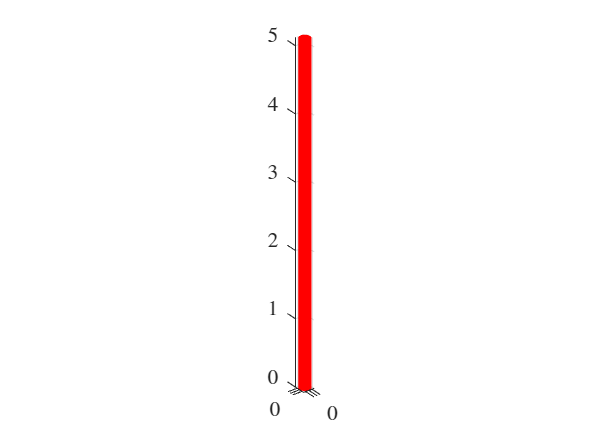


% Draw the rocket:

drawRocket(r)

### Check Environment conditions

env = Environment

env =   Environment with properties:

         date: 25-May-2025
    Elevation: 614
      latlong: [35.3462 -117.8167]



% get the date from the environment. Should default to current date.
env.date

ans = datetime
   25-May-2025



% get the location information for the launch site:
loc = env.latlong

loc =    35.3462 -117.8167


ans = 614